# Evaluación de Tensiones Residuales

Esquema general del cálculo:

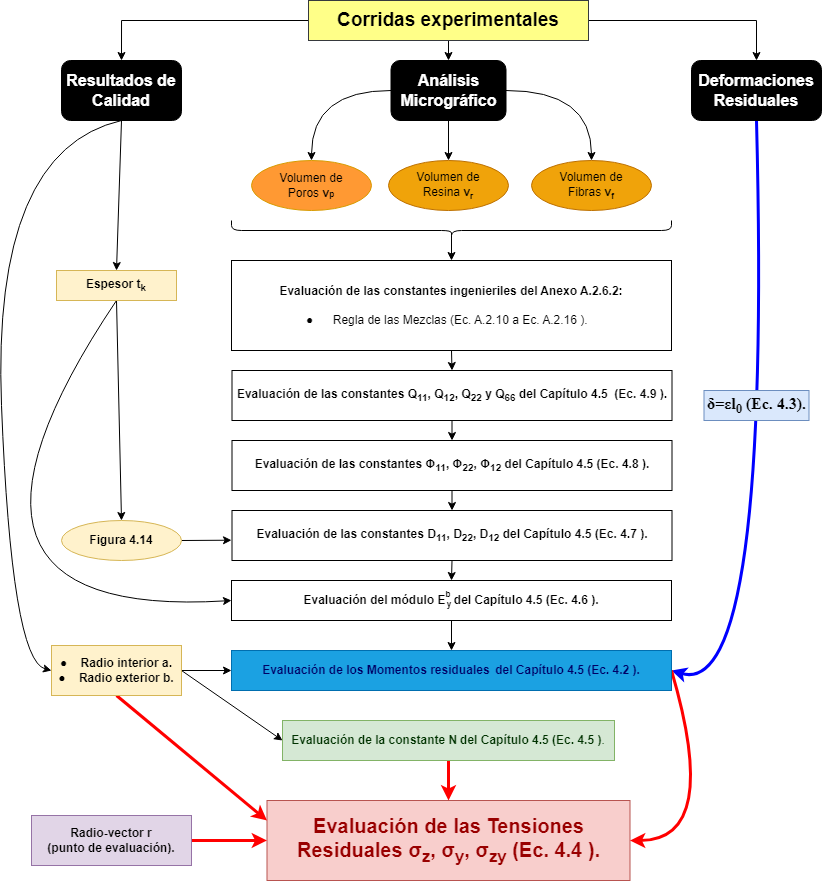

## Constantes ingenieriles de la Corrida 1:

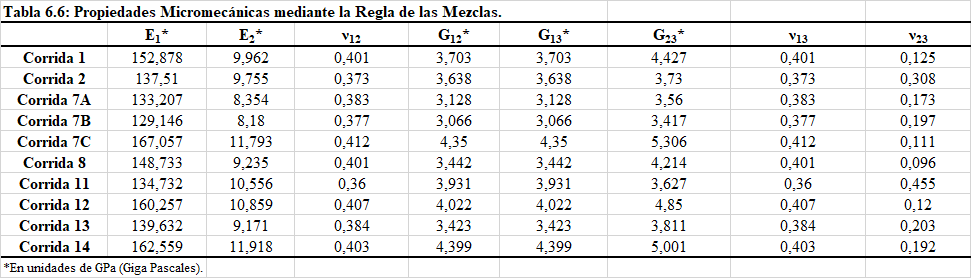

**E****1: **152,878 GPa

**E****2: **9,962 GPa

**ν****12: **0,401

**G****12: **3,703 GPa

**G****13: **3,703 GPa

**G****23: **4,427 GPa

**ν****13: **0,401 

**ν****23: **0,125

E1=152.878; % GPa
E2=9.962; % GPa
NU12=0.401;
G12=3.703; % GPa

## Evaluación de las Constantes Q:

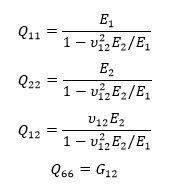

Q11=E1/(1-(NU12^2)*(E2/E1)); % GPa
Q22=E2/(1-(NU12^2)*(E2/E1)); % GPa
Q12=(NU12*E2)/(1-(NU12^2)*(E2/E1)); % GPa
Q66=G12; % GPa

## Evaluación de las Constantes Φ:

En este caso, para la Corrida 1, están los ángulos de las capas 1 a 10 de 89º, 45º y 5º.

Llamamos a la finción "evaluarPHI" para saber en nuestro caso cuanto valen PHI_11, PHI_22 y PHI_12 para la Corrida 1:

% Función para calcular PHI_11, PHI_22 y PHI_12:
corrida1_PHI_5 = evaluarPHI(Q11, Q22, Q12, Q66, 5); % GPa
corrida1_PHI_45 = evaluarPHI(Q11, Q22, Q12, Q66, 45); % GPa
corrida1_PHI_89 = evaluarPHI(Q11, Q22, Q12, Q66, 89); % GPa

## Evaluación de las Constantes D:

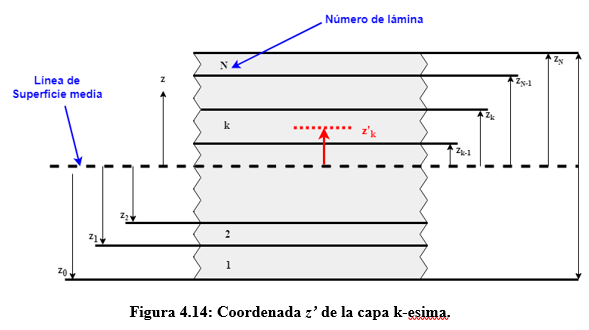

Los espesores de cada capa son como siguen:

**Corrida 1: **1,75 mm

**Corrida 2: **1,52 mm

**Corrida 7A: **1,7 mm

**Corrida 7B: **1,84 mm

**Corrida 7C: **1,52 mm 

**Corrida 8: **1,39 mm 

**Corrida 11: **2,99 mm 

**Corrida 12: **2,65 mm 

**Corrida 13: **2,66 mm 

**Corrida 14: **3,4 mm 

Dado un vector con 10 componentes con los angulos de cada capa:

corrida_1 = [89,89,45,45,5,5,45,45,89,89];% En grados
espesor = 1.75;% En mm

Entonces evaluamos los Dij en base al vector de entrada:

corrida1_D=evaluarD(Q11, Q22, Q12, Q66,corrida_1,espesor);% GPa mm^3

## Calculo del Módulo ${\mathit{\mathbf{E}}}_{\mathit{\mathbf{y}}}^{\mathit{\mathbf{b}}}$:

E_yb = 12*(corrida1_D(1)*corrida1_D(2)-(corrida1_D(3)^2))/((espesor^3)*corrida1_D(1));% GPa

## Calculo del Módulo ${\mathit{\mathbf{E}}}_x^{\mathit{\mathbf{b}}}$:

E_xb = 12*(corrida1_D(1)*corrida1_D(2)-(corrida1_D(3)^2))/((espesor^3)*corrida1_D(2));% GPa

## Evaluación de los momentos residuales:

Deformación medida:

epsilon = -0.000297;

Desplazamiento: $\delta =\varepsilon *l_0$, donde $l_0 =3,175\;\textrm{mm}$.

desplazamiento=epsilon*3.175;% mm

El radio menor a y el radio mayor b son:

a=50.74; % mm
b=52.49; % mm

Finalmente, el momento se calcula como:

### -Momento en Y:

my=((desplazamiento/a)*(E_yb*1000)*(log(b/a))*(((b^2)-(a^2))^2-4*(a^2)*(b^2)*((log(b/a))^2)))/(16*pi*((b^2)-(a^2)));% N

### -Momento en X:

mx=((desplazamiento/a)*(E_xb*1000)*(log(b/a))*(((b^2)-(a^2))^2-4*(a^2)*(b^2)*((log(b/a))^2)))/(16*pi*((b^2)-(a^2)));% N

## Evaluación de las Tensiones Residuales:

Constante N:

N=(((b^2)-(a^2))^2)-4*(a^2)*(b^2)*((log(b/a))^2);% mm^4

Y finalmente las tensiones residuales se calculan como:

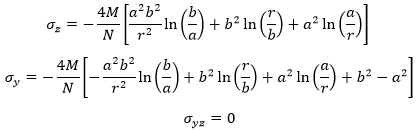

### -Tensiones Residuales basadas en My:

sigma_z_a_corrida_1_y=sigma_z(a,my,N,a,b);% MPa (N/mm^2)
sigma_z_b_corrida_1_y=sigma_z(b,my,N,a,b);% MPa (N/mm^2)
sigma_y_a_corrida_1_y=sigma_y(a,my,N,a,b);% MPa (N/mm^2)
sigma_y_b_corrida_1_y=sigma_y(b,my,N,a,b);% MPa (N/mm^2)

### -Tensiones Residuales basadas en Mx:

sigma_z_a_corrida_1_x=sigma_z(a,mx,N,a,b);% MPa (N/mm^2)
sigma_z_b_corrida_1_x=sigma_z(b,mx,N,a,b);% MPa (N/mm^2)
sigma_y_a_corrida_1_x=sigma_y(a,mx,N,a,b);% MPa (N/mm^2)
sigma_y_b_corrida_1_x=sigma_y(b,mx,N,a,b);% MPa (N/mm^2)

# Evaluación del modelo predictivo de las tensiones residuales

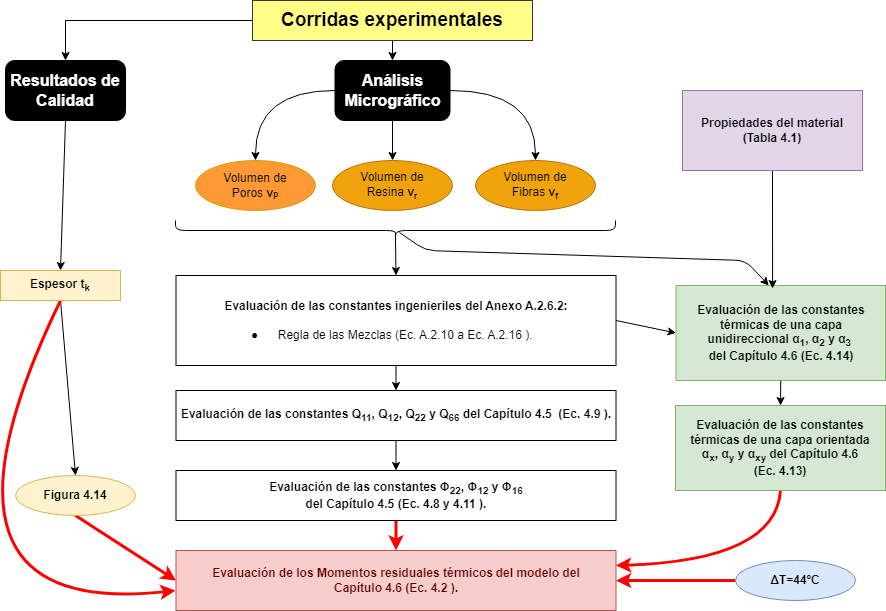

                         **V****f**            **V****m**          **E****1*******          **α****1********          **α****2******** 

  **Corrida 1**  0,63387  0,33229  152,878  4,85E-08  2,29E-05

## Calcular los Alfas de capa unidireccional:

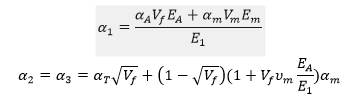

Vf_corrida_1 = 0.63387;
Vm_corrida_1 = 0.33229;
alfa_a = -0.00000038; % 1/ºC
alfa_t = 0.0000095; % 1/ºC
alfa_m = 0.0000576; % 1/ºC
E_a = 239.400; % GPa
E_m = 3.400; % GPa
NU_m = 0.31;
alfa_1 = (alfa_a * Vf_corrida_1 * E_a + alfa_m * Vm_corrida_1 * E_m)/E1;
alfa_2 = alfa_t * (Vf_corrida_1^0.5) + (1 - (Vf_corrida_1^0.5))*(1 + Vf_corrida_1 * NU_m * (E_a / E1)) * alfa_m;

## Calcular los Alfas de capa orientada:

alfas_corrida_1 = [];
alfas_corrida_1(1,1) = alfa_x (alfa_1, alfa_2, 5);
alfas_corrida_1(1,2) = alfa_y (alfa_1, alfa_2, 5);
alfas_corrida_1(1,3) = alfa_xy (alfa_1, alfa_2, 5);
alfas_corrida_1(2,1) = alfa_x (alfa_1, alfa_2, 45);
alfas_corrida_1(2,2) = alfa_y (alfa_1, alfa_2, 45);
alfas_corrida_1(2,3) = alfa_xy (alfa_1, alfa_2, 45);
alfas_corrida_1(3,1) = alfa_x (alfa_1, alfa_2, 89);
alfas_corrida_1(3,2) = alfa_y (alfa_1, alfa_2, 89);
alfas_corrida_1(3,3) = alfa_xy (alfa_1, alfa_2, 89);

## Evaluación de los Momentos Residuales Térmicos:

Mx = momento_termico (Q11, Q22, Q12, Q66, corrida_1, espesor, alfa_1, alfa_2);

# Evaluación de otro modelo predictivo de tensiones reisudales

Lo que mide la galga es $\varepsilon_y^0$. Los exfuerzos y momentos externos aplicados son nulos por lo que Nx=Ny=Nxy=0 y Mx=My=Mxy=0. Los laminados son simetricos, por lo que los Bij son nulos. 

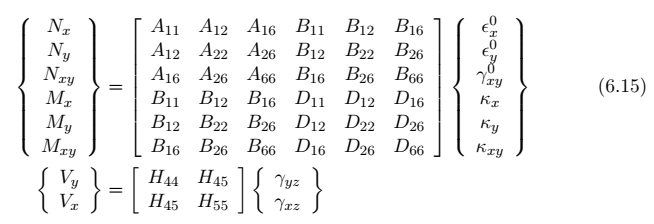

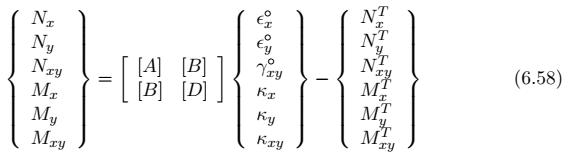

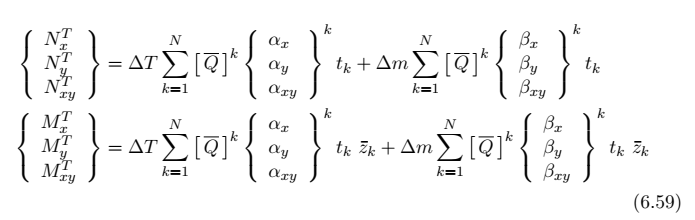

Entonces se cumple lo siguiente (tener en cuenta que solo estamos prediciendo lo que mide la galga, es decir $\varepsilon_y^0$.):


$$N_y =0=A_{22} \;\varepsilon_y^0 -N_y^T \;\Rightarrow \varepsilon_y^0 =\frac{\Delta T}{A_{22} }\;\sum_{k=1}^N \left(\Phi_{12}^k \;\alpha_x^k +\Phi_{22}^k \;\alpha_y^k +\Phi_{26}^k \;\alpha_{\mathrm{xy}}^k \right)*t_k \;$$


$\Delta T$=-44ºC.

$t_k$=1.75 mm.

$A_{22}$:

E1=152.878; % GPa
E2=9.962; % GPa
NU12=0.401;
G12=3.703; % GPa


Q11=E1/(1-(NU12^2)*(E2/E1)); % GPa
Q22=E2/(1-(NU12^2)*(E2/E1)); % GPa
Q12=(NU12*E2)/(1-(NU12^2)*(E2/E1)); % GPa
Q66=G12; % GPa

corrida_1 = [89,89,45,45,5,5,45,45,89,89];% En grados
espesor = 1.75;% En mm

Vf_corrida_1 = 0.63387;
Vm_corrida_1 = 0.33229;
alfa_a = -0.00000038; % 1/ºC
alfa_t = 0.0000095; % 1/ºC
alfa_m = 0.0000576; % 1/ºC
E_a = 239.400; % GPa
E_m = 3.400; % GPa
NU_m = 0.31;

alfa_1 = (alfa_a * Vf_corrida_1 * E_a + alfa_m * Vm_corrida_1 * E_m)/E1;
alfa_2 = alfa_t * (Vf_corrida_1^0.5) + (1 - (Vf_corrida_1^0.5))*(1 + Vf_corrida_1 * NU_m * (E_a / E1)) * alfa_m;

datos=[152.878	9.962	0.401	3.703
137.51	9.755	0.373	3.638
133.207	8.354	0.383	3.128
129.146	8.18	0.377	3.066
167.057	11.793	0.412	4.35
148.733	9.235	0.401	3.442
134.732	10.556	0.36	3.931
160.257	10.859	0.407	4.022
139.632	9.171	0.384	3.423
162.559	11.918	0.403	4.399];

Matriz_Q=[];
for i = 1:1:10
    Matriz_Q(i,1)=datos(i,1)/(1-((datos(i,3))^2)*((datos(i,2))/(datos(i,1)))); %%%%%% Q11
    Matriz_Q(i,2)=(datos(i,2))/(1-((datos(i,3))^2)*((datos(i,2))/(datos(i,1))));%%%%%%% Q22
    Matriz_Q(i,3)=((datos(i,3))*(datos(i,2)))/(1-((datos(i,3))^2)*(datos(i,2)/(datos(i,1))));%%%%%%% Q12
    Matriz_Q(i,4)=(datos(i,4));%%%%%%% Q66
end

A22_Corrida_1 = evaluarA22(Q11, Q22, Q12, Q66, corrida_1, espesor);
NyT_Corrida_1 = evaluarNyT(Q11, Q22, Q12, Q66, corrida_1, espesor, alfa_1, alfa_2);
epsilon_0_y_corrida_1 = (-44 * NyT_Corrida_1) / A22_Corrida_1;

## Evaluacion de todas las tensiones residuales según este mátodo:

Matriz_volumen_fibra_resina = [0.63387	0.33229;
0.56956	0.34044;
0.55075	0.39916;
0.53366	0.40806;
0.69386	0.27846;
0.61617	0.35942;
0.55833	0.31415;
0.6651	0.30366;
0.57811	0.36254;
0.67511	0.27569];

Matriz_corridas=[89 89 45 45 5 5 45 45 89 89
    89 89 45 45 5 5 45 45 89 89
    45 45 45 45 45 45 45 45 45 45
    45 45 45 45 45 45 45 45 45 45
    45 45 45 45 45 45 45 45 45 45
    45 45 45 45 45 45 45 45 45 45
    89 89 45 45 5 5 45 45 89 89
    89 89 45 45 5 5 45 45 89 89
    89 89 5 5 89 89 5 5 89 89
    89 89 5 5 89 89 5 5 89 89
    ];

Matriz_espesores=[
    1.75
1.52
1.7
1.84
1.52
1.39
2.99
2.65
2.66
3.4
    ];

alfa_a = -0.00000038; % 1/ºC
alfa_t = 0.0000095; % 1/ºC
alfa_m = 0.0000576; % 1/ºC
E_a = 239.400; % GPa
E_m = 3.400; % GPa
NU_m = 0.31;

Matriz_A22 = zeros(10,1);
Matriz_NyT = zeros(10,1);
Matriz_epsilon_0 =zeros(10,1);
capas=zeros(10,1);
Matriz_alfa=[];
for i = 1:1:10
    for j = 1:1:10
        capas(j)=Matriz_corridas(i,j);
    end
    Matriz_A22(i,1) = evaluarA22(Matriz_Q(i,1), Matriz_Q(i,2), Matriz_Q(i,3), Matriz_Q(i,4), capas, Matriz_espesores(i));
    Vf=Matriz_volumen_fibra_resina(i,1);
    Vm=Matriz_volumen_fibra_resina(i,2);
    E11=datos(i,1);
    Matriz_alfa(i,1) = (alfa_a * Vf * E_a + alfa_m * Vm * E_m)/E11;
    Matriz_alfa(i,2) = alfa_t * (Vf^0.5) + (1 - (Vf^0.5))*(1 + Vf * NU_m * (E_a / E11)) * alfa_m;
    Matriz_NyT(i,1) = evaluarNyT(Matriz_Q(i,1), Matriz_Q(i,2), Matriz_Q(i,3), Matriz_Q(i,4), capas, Matriz_espesores(i), Matriz_alfa(i,1), Matriz_alfa(i,2));
    Matriz_epsilon_0(i,1) = (-44 * Matriz_NyT(i,1)) / Matriz_A22(i,1);
end

# Evaluación de TODAS las tensiones residuales con MATLAB

Primero introducimos una matriz vacia para poner todos los datos:

datos=[152.878	9.962	0.401	3.703
137.51	9.755	0.373	3.638
133.207	8.354	0.383	3.128
129.146	8.18	0.377	3.066
167.057	11.793	0.412	4.35
148.733	9.235	0.401	3.442
134.732	10.556	0.36	3.931
160.257	10.859	0.407	4.022
139.632	9.171	0.384	3.423
162.559	11.918	0.403	4.399];

Las primeras cuatro columnas tienen los valores de E1, E2, NU12 y G12 respectivamente. 

## LLenamos las otras columnas con los calculos de las Constantes Q:

Matriz_Q=[];
for i = 1:1:10
    Matriz_Q(i,1)=datos(i,1)/(1-((datos(i,3))^2)*((datos(i,2))/(datos(i,1)))); %%%%%% Q11
    Matriz_Q(i,2)=(datos(i,2))/(1-((datos(i,3))^2)*((datos(i,2))/(datos(i,1))));%%%%%%% Q22
    Matriz_Q(i,3)=((datos(i,3))*(datos(i,2)))/(1-((datos(i,3))^2)*(datos(i,2)/(datos(i,1))));%%%%%%% Q12
    Matriz_Q(i,4)=(datos(i,4));%%%%%%% Q66
end

## Evaluamos PHI para cada Corrida (Atenti que algunas no tienen por que calcular PHI en determinados angulos):

Matriz_PHI=[];
for i = 1:1:10
    Matriz_PHI(i,1) = evaluarPHI11(Matriz_Q(i,1), Matriz_Q(i,2), Matriz_Q(i,3), Matriz_Q(i,4), 5);% PHI11 5
    Matriz_PHI(i,2)= evaluarPHI11(Matriz_Q(i,1), Matriz_Q(i,2), Matriz_Q(i,3), Matriz_Q(i,4), 45);% PHI11 45
    Matriz_PHI(i,3)= evaluarPHI11(Matriz_Q(i,1), Matriz_Q(i,2), Matriz_Q(i,3), Matriz_Q(i,4), 89);% PHI11 89
    Matriz_PHI(i,4) = evaluarPHI22(Matriz_Q(i,1), Matriz_Q(i,2), Matriz_Q(i,3), Matriz_Q(i,4), 5);% PHI11 5
    Matriz_PHI(i,5)= evaluarPHI22(Matriz_Q(i,1), Matriz_Q(i,2), Matriz_Q(i,3), Matriz_Q(i,4), 45);% PHI11 45
    Matriz_PHI(i,6)= evaluarPHI22(Matriz_Q(i,1), Matriz_Q(i,2), Matriz_Q(i,3), Matriz_Q(i,4), 89);% PHI11 89
    Matriz_PHI(i,7) = evaluarPHI12(Matriz_Q(i,1), Matriz_Q(i,2), Matriz_Q(i,3), Matriz_Q(i,4), 5);% PHI11 5
    Matriz_PHI(i,8)= evaluarPHI12(Matriz_Q(i,1), Matriz_Q(i,2), Matriz_Q(i,3), Matriz_Q(i,4), 45);% PHI11 45
    Matriz_PHI(i,9)= evaluarPHI12(Matriz_Q(i,1), Matriz_Q(i,2), Matriz_Q(i,3), Matriz_Q(i,4), 89);% PHI11 89
end


## Evaluamos las D, necesiamos llenar los datos de los angulos de cada corrida y el espesor:

Matriz_corridas=[89 89 45 45 5 5 45 45 89 89
    89 89 45 45 5 5 45 45 89 89
    45 45 45 45 45 45 45 45 45 45
    45 45 45 45 45 45 45 45 45 45
    45 45 45 45 45 45 45 45 45 45
    45 45 45 45 45 45 45 45 45 45
    89 89 45 45 5 5 45 45 89 89
    89 89 45 45 5 5 45 45 89 89
    89 89 5 5 89 89 5 5 89 89
    89 89 5 5 89 89 5 5 89 89
    ];

Matriz_espesores=[
    1.75
1.52
1.7
1.84
1.52
1.39
2.99
2.65
2.66
3.4
    ];

Matriz_D=[];
for j = 1:1:10
    capa_corrida_iesima=[Matriz_corridas(j,1),Matriz_corridas(j,2),Matriz_corridas(j,3),Matriz_corridas(j,4),Matriz_corridas(j,5),Matriz_corridas(j,6),Matriz_corridas(j,7),Matriz_corridas(j,8),Matriz_corridas(j,9),Matriz_corridas(j,10)];
    Matriz_D(j,1)=evaluarD11(Matriz_Q(j,1), Matriz_Q(j,2), Matriz_Q(j,3), Matriz_Q(j,4), capa_corrida_iesima, Matriz_espesores(j));% D11
    Matriz_D(j,2)=evaluarD22(Matriz_Q(j,1), Matriz_Q(j,2), Matriz_Q(j,3), Matriz_Q(j,4), capa_corrida_iesima, Matriz_espesores(j));% D22
    Matriz_D(j,3)=evaluarD12(Matriz_Q(j,1), Matriz_Q(j,2), Matriz_Q(j,3), Matriz_Q(j,4), capa_corrida_iesima, Matriz_espesores(j));% D12
end

## Evaluar el módulo Ex para cada corrida:

Matriz_Ex=[];
for j = 1:1:10
    Matriz_Ex(j,1) = 12*(Matriz_D(j,1)*Matriz_D(j,2)-(Matriz_D(j,3)^2))/((Matriz_espesores(j)^3)*Matriz_D(j,2));% GPa
end

## Evaluación de los momentos residuales:

Matriz_calculo_momentos=[-0.00094298	50.74	52.49
-0.00159703	50.76	52.28
-0.00024765	50.86	52.56
0.00110702	50.93	52.77
-0.00021484	50.96	52.48
-0.00006985	50.84	52.23
-0.00110173	50.66	53.65
-0.00247968	50.75	53.4
-0.00114935	50.59	53.25
-0.00170815	50.73	54.13];
Matriz_momentos_x=[];
for j = 1:1:10
    Matriz_momentos_x(j,1) = m_x(Matriz_Ex(j), Matriz_calculo_momentos(j,1), Matriz_calculo_momentos(j,2), Matriz_calculo_momentos(j,3));
end

## Evaluar las tensiones residuales en diez puntos:

Matriz_TR_Z = [];
Matriz_TR_Y = [];
Matriz_N = [];
for ii = 1:1:10
    a_ii=Matriz_calculo_momentos(ii,2);
    t_ii=Matriz_espesores(ii);
    b_ii=a_ii+t_ii;
    N_ii=(((b_ii^2)-(a_ii^2))^2)-4*(a_ii^2)*(b_ii^2)*((log(b_ii/a_ii))^2);% mm^4
    Matriz_N(ii) = N_ii;
    for jj = 1:1:11
        r=a_ii+(t_ii/10)*(jj-1);
        Matriz_TR_Z(ii,jj) = sigma_z (r, Matriz_momentos_x(ii), N_ii, a_ii, b_ii);% MPa (N/mm^2)
        Matriz_TR_Y(ii,jj) = sigma_y (r, Matriz_momentos_x(ii), N_ii, a_ii, b_ii);% MPa (N/mm^2)
    end
end

# Funciones:

%Fórmulas de Tensiones Residuales
function sigmaz=sigma_z(r,m,N,a,b)
    sigmaz = (-4*m/N)*(((a^2)*(b^2)/(r^2))*(log(b/a))+(b^2)*(log(r/b))+(a^2)*(log(a/r)));
end
function sigmay=sigma_y(r,m,N,a,b)
    sigmay = (-4*m/N)*(-((a^2)*(b^2)/(r^2))*(log(b/a))+(b^2)*(log(r/b))+(a^2)*(log(a/r))+(b^2)-(a^2));
end
%Cálculo de constantes Dij
function [D] = evaluarD(q11, q22, q12, q66, capas, espesor)
    D11 = 0;
    D22 = 0;
    D12 = 0;
    for i = 1:1:10
        t = deg2rad(capas(i));
        tk = espesor/10;
        z = -espesor/2+tk/2+tk*(i-1);
        PHI_11 = q11*(cos(t)^4)+2*(q12+2*q66)*(sin(t)^2)*(cos(t)^2)+q22*(sin(t)^4);
        d11 = PHI_11*(tk*(z^2)+(tk^3)/12);
        D11 = D11+d11;
        PHI_22 = q11*(sin(t)^4)+2*(q12+2*q66)*(sin(t)^2)*(cos(t)^2)+q22*(cos(t)^4);
        d22 = PHI_22*(tk*(z^2)+(tk^3)/12);
        D22 = D22+d22;
        PHI_12 = (q11+q22-4*q66)*(sin(t)^2)*(cos(t)^2)+q12*((sin(t)^4)+(cos(t)^4));
        d12 = PHI_12*(tk*(z^2)+(tk^3)/12);
        D12 = D12+d12;
    end
    D = [D11,D22,D12];
end
function D11 = evaluarD11(q11, q22, q12, q66, capas, espesor)
    D11 = 0;
    for i = 1:1:10
        t = deg2rad(capas(i));
        tk = espesor/10;
        z = -espesor/2+tk/2+tk*(i-1);
        PHI_11 = q11*(cos(t)^4)+2*(q12+2*q66)*(sin(t)^2)*(cos(t)^2)+q22*(sin(t)^4);
        d11 = PHI_11*(tk*(z^2)+(tk^3)/12);
        D11 = D11+d11;
    end
    D11 = D11;
end
function D22 = evaluarD22(q11, q22, q12, q66, capas, espesor)
    D22 = 0;
    for i = 1:1:10
        t = deg2rad(capas(i));
        tk = espesor/10;
        z = -espesor/2+tk/2+tk*(i-1);
        PHI_22 = q11*(sin(t)^4)+2*(q12+2*q66)*(sin(t)^2)*(cos(t)^2)+q22*(cos(t)^4);
        d22 = PHI_22*(tk*(z^2)+(tk^3)/12);
        D22 = D22+d22;
    end
    D22 = D22;
end
function D12 = evaluarD12(q11, q22, q12, q66, capas, espesor)
    D12 = 0;
    for i = 1:1:10
        t = deg2rad(capas(i));
        tk = espesor/10;
        z = -espesor/2+tk/2+tk*(i-1);
        PHI_12 = (q11+q22-4*q66)*(sin(t)^2)*(cos(t)^2)+q12*((sin(t)^4)+(cos(t)^4));
        d12 = PHI_12*(tk*(z^2)+(tk^3)/12);
        D12 = D12+d12;
    end
    D12 = D12;
end
%Cálculo de constantes PHI
function [PHI] = evaluarPHI(q11, q22, q12, q66, tita)
    t = deg2rad(tita);
    PHI_11 = q11*(cos(t)^4)+2*(q12+2*q66)*(sin(t)^2)*(cos(t)^2)+q22*(sin(t)^4);
    PHI_22 = q11*(sin(t)^4)+2*(q12+2*q66)*(sin(t)^2)*(cos(t)^2)+q22*(cos(t)^4);
    PHI_12 = (q11+q22-4*q66)*(sin(t)^2)*(cos(t)^2)+q12*((sin(t)^4)+(cos(t)^4));
    PHI=[PHI_11,PHI_22,PHI_12];
end
function PHI_11 = evaluarPHI11(q11, q22, q12, q66, tita)
    t = deg2rad(tita);
    PHI_11 = q11*(cos(t)^4)+2*(q12+2*q66)*(sin(t)^2)*(cos(t)^2)+q22*(sin(t)^4);
end
function PHI_22 = evaluarPHI22(q11, q22, q12, q66, tita)
    t = deg2rad(tita);
    PHI_22 = q11*(sin(t)^4)+2*(q12+2*q66)*(sin(t)^2)*(cos(t)^2)+q22*(cos(t)^4);
end
function PHI_12 = evaluarPHI12(q11, q22, q12, q66, tita)
    t = deg2rad(tita);
    PHI_12 = (q11+q22-4*q66)*(sin(t)^2)*(cos(t)^2)+q12*((sin(t)^4)+(cos(t)^4));
end
function PHI_16 = evaluarPHI16(q11, q22, q12, q66, tita)
    t = deg2rad(tita);
    PHI_16 = (q11-q12-2*q66)*(sin(t))*(cos(t)^3)+(q12-q22+2*q66)*(sin(t)^3)*(cos(t));
end
% Cálculo de alfas de capa orientada
function alfa_x = alfa_x (alfa_1, alfa_2, tita)
    t = deg2rad(tita);
    alfa_x = alfa_1 * ((cos(t))^2) + alfa_2 * ((sin(t))^2);
end
function alfa_y = alfa_y (alfa_1, alfa_2, tita)
    t = deg2rad(tita);
    alfa_y = alfa_1 * ((sin(t))^2) + alfa_2 * ((cos(t))^2);
end
function alfa_xy = alfa_xy (alfa_1, alfa_2, tita)
    t = deg2rad(tita);
    alfa_xy = 2 * (cos(t)) * (sin(t)) * (alfa_1 - alfa_2);
end
%calculo de momento residual térmico
function momento_termico1 = momento_termico(q11, q22, q12, q66, capas, espesor, alfa_1, alfa_2)
    m_termico = 0;
    for i = 1:1:10
        t = deg2rad(capas(i));
        tk = espesor / 10;
        z = -espesor / 2+ tk / 2 + tk * (i-1);
        PHI_11 = q11 * (cos(t)^4) + 2 * (q12 + 2 * q66) * (sin(t)^2) * (cos(t)^2) + q22 * (sin(t)^4);
        PHI_22 = q11 * (sin(t)^4) + 2 * (q12 + 2 * q66) * (sin(t)^2) * (cos(t)^2) + q22 * (cos(t)^4);
        PHI_16 = (q11 - q12 - 2 * q66) * (sin(t)) * (cos(t)^3) + (q12 - q22 + 2 * q66) * (sin(t)^3) * (cos(t));
        alfa_x = alfa_1 * ((cos(t))^2) + alfa_2 * ((sin(t))^2);
        alfa_y = alfa_1 * ((sin(t))^2) + alfa_2 * ((cos(t))^2);
        alfa_xy = 2 * (cos(t)) * (sin(t)) * (alfa_1 - alfa_2);
        momento = (PHI_11 * alfa_x + PHI_22 * alfa_y + PHI_16 * alfa_xy) * z;
        m_termico = m_termico + momento;
    end
    momento_termico1 = 44 * espesor * m_termico;
end
%calculo momentos:
function m_x = m_x(E_xb, desplazamiento, a, b)
    m_x=((desplazamiento/a)*(E_xb*1000)*(log(b/a))*(((b^2)-(a^2))^2-4*(a^2)*(b^2)*((log(b/a))^2)))/(16*pi*((b^2)-(a^2)));% N
end
%Calcular A22
function A22 = evaluarA22(q11, q22, q12, q66, capas, espesor)
    A22 = 0;
    for i = 1:1:10
        t = deg2rad(capas(i));
        tk = espesor/10;
        z = -espesor/2+tk/2+tk*(i-1);
        PHI_22 = q11*(sin(t)^4)+2*(q12+2*q66)*(sin(t)^2)*(cos(t)^2)+q22*(cos(t)^4);
        a22 = PHI_22*tk;
        A22 = A22+a22;
    end
    A22 = A22;
end
%Evaluar NyT
function NyT = evaluarNyT(q11, q22, q12, q66, capas, espesor, alfa_1, alfa_2)
    NyT = 0;
    for i = 1:1:10
        t=deg2rad(capas(i));
        PHI_12k = (q11 + q22 - 4 * q66) * (sin(t)^2) * (cos(t)^2) + q12 * ((sin(t)^4) + (cos(t)^4));
        PHI_22k = q11 * (sin(t)^4) + 2 * (q12 + 2 * q66) * (sin(t)^2) * (cos(t)^2) + q22 * (cos(t)^4);
        PHI_26k = (q11 - q12 - 2 * q66) * (sin(t)^3) * (cos(t)) + (q12 - q22 + 2 * q66) * (sin(t)) * (cos(t)^3);
        alfa_xk = alfa_1 * ((cos(t))^2) + alfa_2 * ((sin(t))^2);
        alfa_yk = alfa_1 * ((sin(t))^2) + alfa_2 * ((cos(t))^2);
        alfa_xyk = 2 * (cos(t)) * (sin(t)) * (alfa_1 - alfa_2);
        NyTk = (PHI_12k)*(alfa_xk)+(PHI_22k)*(alfa_yk)+(PHI_26k)*(alfa_xyk);
        NyT = NyT + NyTk*(espesor/10);
    end
    NyT = NyT;
end